# **ANALISIS DENAVIT HARTENBERG**

syms theta1 theta2 l1 l2
T01 = trotz(0)

T01 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T12 = trotz(theta1)*transl(l1,0,0)

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & l_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = trotz(theta2)*transl(l2,0,0)

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

3 sistemas sobre el mismo plano

Ahora, hallar las matrices para un punto *a* que se alcanza con $\theta_1$y $\theta_2$

T03 = T01*T12*T23

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & l_{1}\,\cos\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & l_{1}\,\sin\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

subs(T03, {l1, l2, theta1, theta2},{15, 15, deg2rad(30), deg2rad(30)})

$$ans = \left(\begin{array}{cccc} \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0 & \frac{15\,\sqrt{3}}{2}+\frac{15}{2}\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0 & \frac{15\,\sqrt{3}}{2}+\frac{15}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

# **CINEMATICA INVERSA**

% Punto a encontrar
syms x y l
syms theta3

Sistema de ecuaciones

E1 = simplify(T03(1,4)) == x

$$E1 = l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)=x$$

E2 = simplify(T03(2,4)) == y

$$E2 = l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\sin\left(\theta_{1}\right)=y$$

Para simplificar el procedimiento se asume $l_1$y $l_2$ iguales, en caso de no ser así el resultado más optimo, se debe hacer una traslación en el eje$X$partiendo del resultado obtenido.

- 
$$\theta_3 =\theta_1 +\theta_2$$


E1 = l*(cos(theta3)+cos(theta1)) == x

$$E1 = l\,\left(\cos\left(\theta_{1}\right)+\cos\left(\theta_{3}\right)\right)=x$$

E2 = l*(sin(theta3)+sin(theta1)) == y

$$E2 = l\,\left(\sin\left(\theta_{1}\right)+\sin\left(\theta_{3}\right)\right)=y$$

Suma de cosenos y senos

- 
$$\textrm{Cos}\left(\theta_1 \right)+\textrm{Cos}\left(\theta_2 \right)=2\cdot \textrm{Cos}\left(\frac{\theta_1 +\theta_2 }{2}\right)\cdot \textrm{Cos}\left(\frac{\theta_1 -\theta_2 }{2}\right)$$


- 
$$\textrm{Sen}\left(\theta_1 \right)+\textrm{Sen}\left(\theta_2 \right)=2\cdot \textrm{Sen}\left(\frac{\theta_1 +\theta_2 }{2}\right)\cdot \textrm{Cos}\left(\frac{\theta_1 -\theta_2 }{2}\right)$$


E1 = l*2*cos((theta1+theta3)*.5)*cos((theta1-theta3)/2) == x

$$E1 = 2\,l\,\cos\left(\frac{\theta_{1}}{2}-\frac{\theta_{3}}{2}\right)\,\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)=x$$

E2 = l*2*sin((theta1+theta3)/2)*cos((theta1-theta3)/2) == y

$$E2 = 2\,l\,\cos\left(\frac{\theta_{1}}{2}-\frac{\theta_{3}}{2}\right)\,\sin\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)=y$$

S1 = theta1 + theta3 == atan2(y,x)*2

$$S1 = \theta_{1}+\theta_{3}=2\,\text{atan2}\left(y,x\right)$$

s1 = (theta1 + theta3)/2;
S2 = cos((theta1-theta3)/2) == x/(2*l*cos(s1))

$$S2 = \cos\left(\frac{\theta_{1}}{2}-\frac{\theta_{3}}{2}\right)=\frac{x}{2\,l\,\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)}$$

s2 = x/(2*l*cos(s1))

$$s2 = \frac{x}{2\,l\,\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)}$$

S3 = theta1 - theta3 == 2*atan2(sqrt(1-s2^2),s2)

$$S3 = \theta_{1}-\theta_{3}=2\,\text{atan2}\left(2\,\sqrt{1-\frac{x^{2}}{4\,l^{2}\,{\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)}^{2}}},\frac{x}{l\,\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)}\right)$$

- Sabiendo que, $\cos \left(\frac{\theta_1 }{2}-\frac{\theta_3 }{2}\right)=\frac{x}{2\cdot l\cdot \,\cos \left(\textrm{atan2}\left(y,x\right)\right)}$

- 
$$\beta =\theta_1 +\theta_3$$


- 
$$\gamma =\theta_1 -\theta_3$$


- $\theta_1 =\frac{\beta +\gamma }{2}$, con $\theta_1$ se halla $\theta_3$

- 
$$\theta_2 =\theta_3 -\theta_1$$


# TESTEO DE LA SOLUCIÓN

clear l x y theta1 theta2 theta3
format longG
x = 7.8;
y = 21;
l = 15;
beta = 2*atan2(y,x);

    
$$\beta =\theta_1 +\theta_3$$


cost1mt3 = x/(2*l*cos(beta/2));
gamma = 2*atan2(sqrt(1-cost1mt3^2),cost1mt3);

    
$$\gamma =\theta_1 -\theta_3$$


theta1 = (beta+gamma)/2;
theta3 = beta - theta1;
theta2 = theta3 - theta1;
x2 = l*cos(theta1)

x2 =          -5.45266708675023


y2 = l*sin(theta1)

y2 =           13.9738477750787


theta1 = rad2deg(theta1)

theta1 =           111.315984349771


theta2 = rad2deg(theta2)

theta2 =          -83.3848391272155


Resultado esperado, cinematica inversa hallada correctamente

# PERFIL DE POSICION, VELOCIDAD, ACELERACION Y JERK

t_values = linspace(0, 2*pi, 600);
s = 0.7; % Size
leafs = 8;
r = 3*pi/2; % rotation
roundness = 10;
Ox = 9; % Offset x
Oy = 23; % Offset y
l = 20; % Arm's long
x = s*(cos(leafs * t_values + r) + roundness) .* cos(t_values) + Ox;
y = s*(cos(leafs * t_values + r) + roundness) .* sin(t_values) + Oy;
b = atan2(y,x)*2;
gamma = 2 * atan2(sqrt(1-(x ./ (2*l*cos(b/2))) .^ 2),x ./ (2 * l * cos(b/2)));
theta1_values = (b + gamma) / 2;
theta2_values = b - 2 .* theta1_values;

#### Pos**ición **$\theta_1$

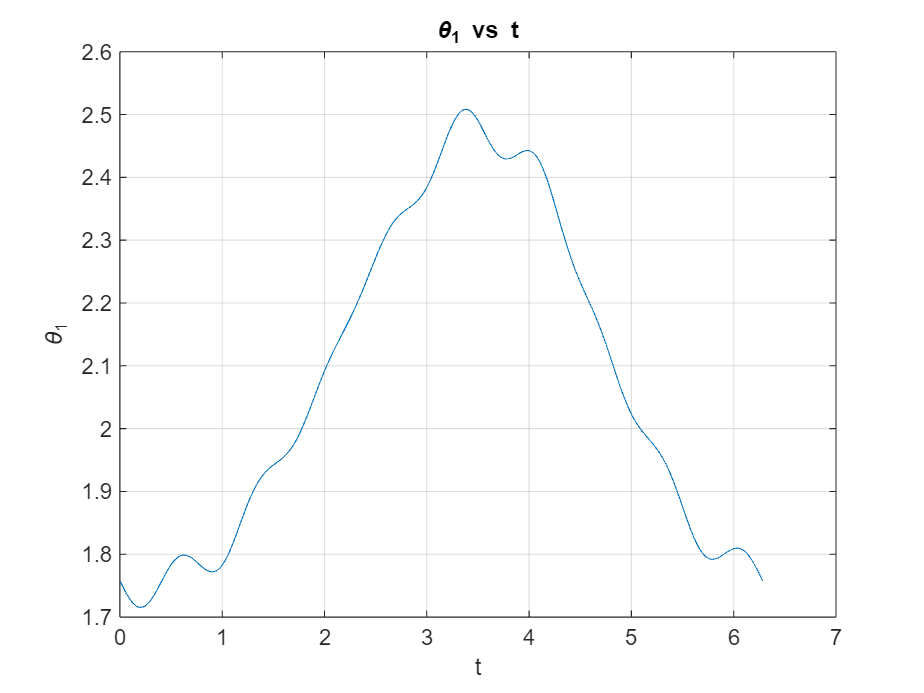

plot(t_values, theta1_values);
xlabel('t');
ylabel('\theta_1');
title('\theta_1 vs t');
grid on;

**Posición **$\theta_2$

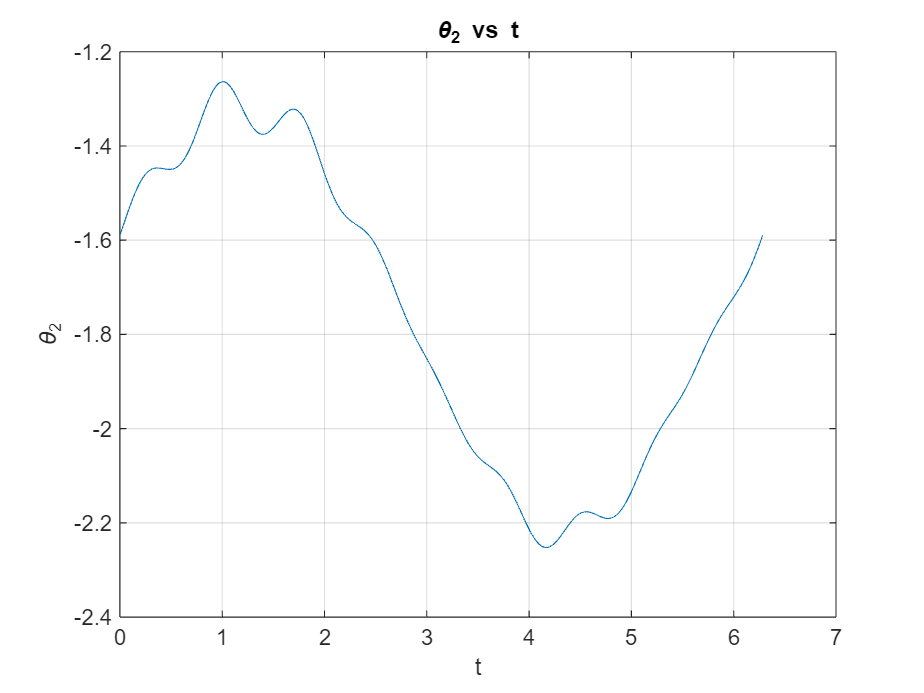

plot(t_values, theta2_values);
xlabel('t');
ylabel('\theta_2');
title('\theta_2 vs t');
grid on;

**Velocidad **$\dot{\theta_1 }$

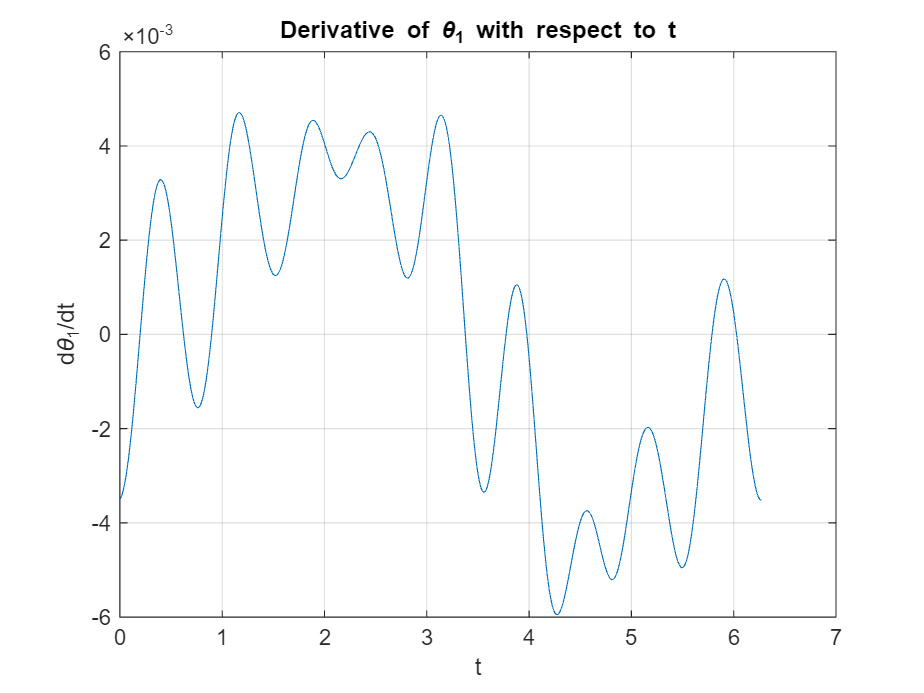

dt_theta1_values = diff(theta1_values);
plot(t_values(1:599), dt_theta1_values);
xlabel('t');
ylabel('d\theta_1/dt');
title('Derivative of \theta_1 with respect to t');
grid on;

**Velocidad **$\dot{\theta_2 }$

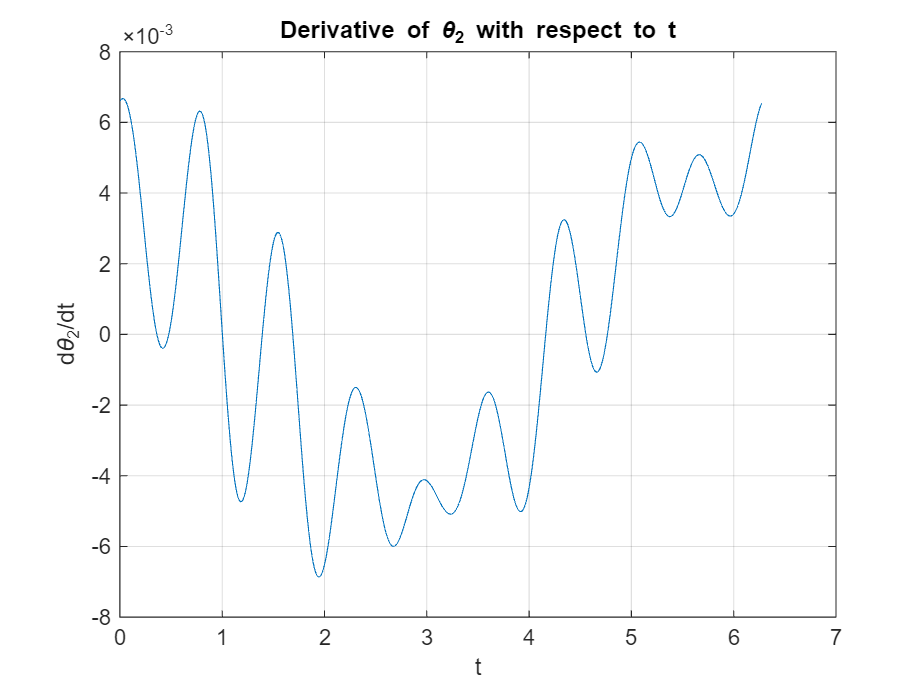

dt_theta2_values = diff(theta2_values);
plot(t_values(1:599), dt_theta2_values);
xlabel('t');
ylabel('d\theta_2/dt');
title('Derivative of \theta_2 with respect to t');
grid on;

**Aceleración **$\ddot{\theta_1 }$

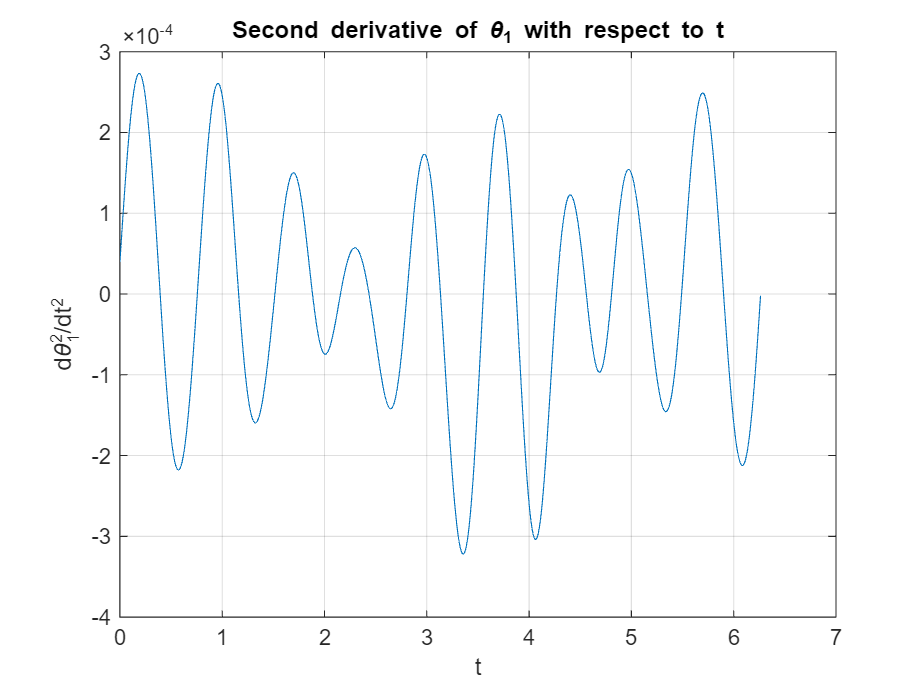

dt2_theta1_values = diff(dt_theta1_values);
plot(t_values(1:598), dt2_theta1_values);
xlabel('t');
ylabel('d\theta_1^2/dt^2');
title('Second derivative of \theta_1 with respect to t');
grid on;

**Aceleración **$\ddot{\theta_2 }$

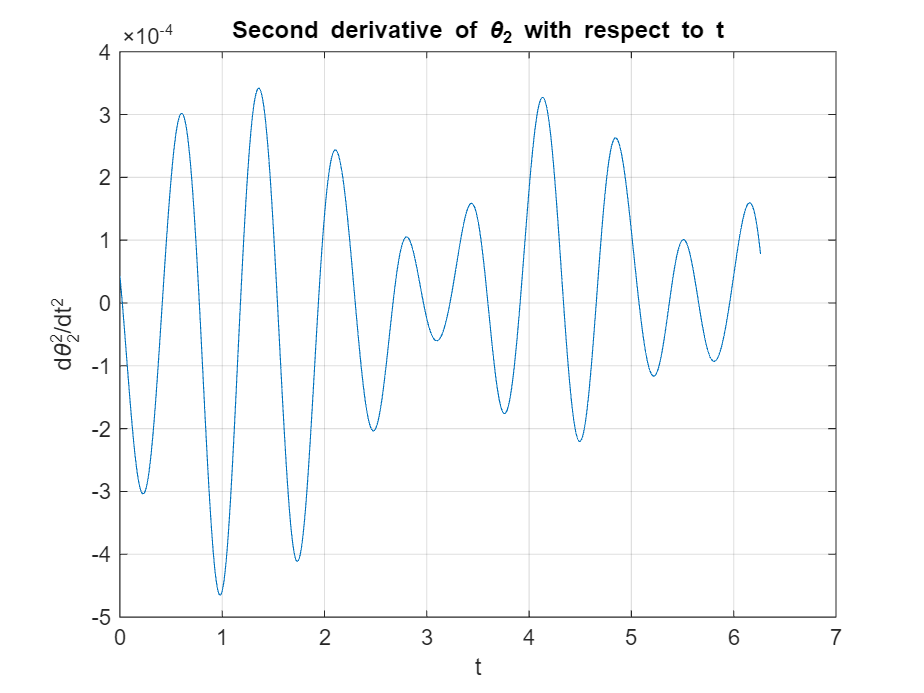

dt2_theta2_values = diff(dt_theta2_values);
plot(t_values(1:598), dt2_theta2_values);
xlabel('t');
ylabel('d\theta_2^2/dt^2');
title('Second derivative of \theta_2 with respect to t');
grid on;

**Jerk **$\dot{\alpha_1 }$

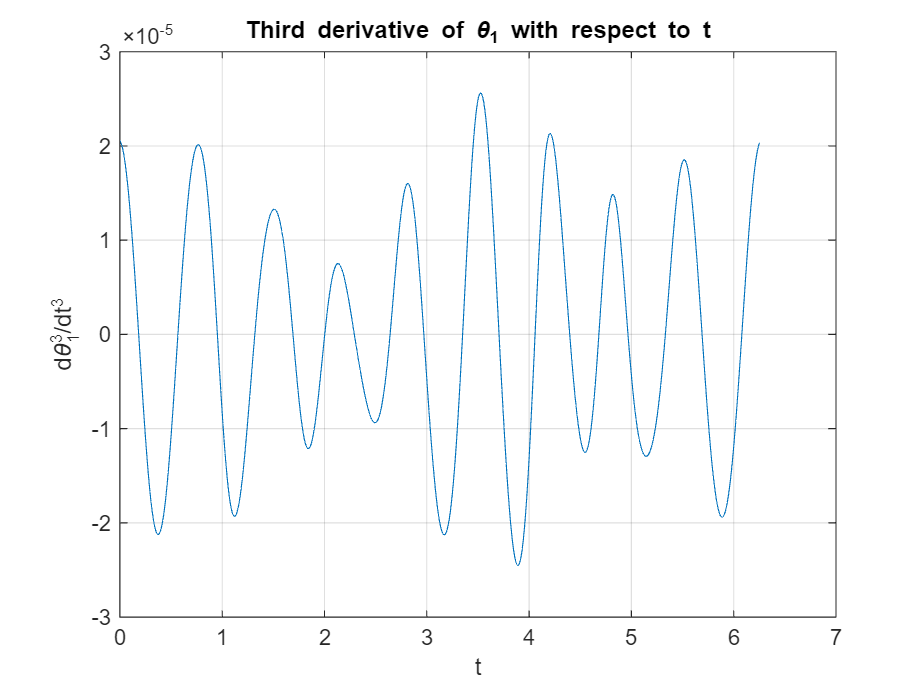

dt3_theta1_values = diff(dt2_theta1_values);
plot(t_values(1:597), dt3_theta1_values);
xlabel('t');
ylabel('d\theta_1^3/dt^3');
title('Third derivative of \theta_1 with respect to t');
grid on;

**Jerk **$\dot{\alpha_2 }$

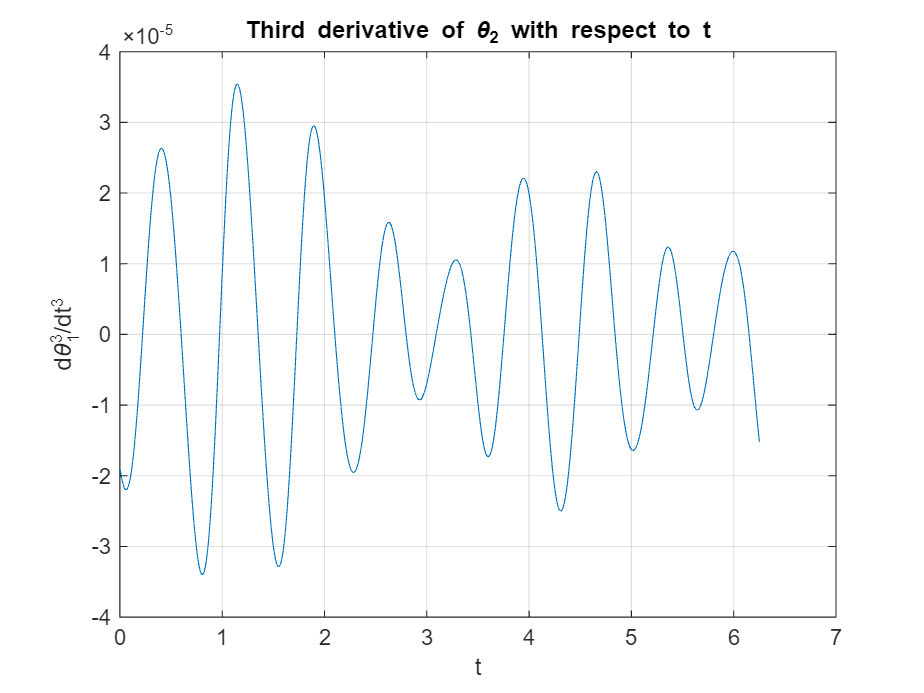

dt3_theta2_values = diff(dt2_theta2_values);
plot(t_values(1:597), dt3_theta2_values);
xlabel('t');
ylabel('d\theta_1^3/dt^3');
title('Third derivative of \theta_2 with respect to t');
grid on;